根据输入的图形对象，返回一个尽可能不遮挡图形的图例位置

## 语法

## 示例

右上角较为空旷，因此图例将位于右上角：

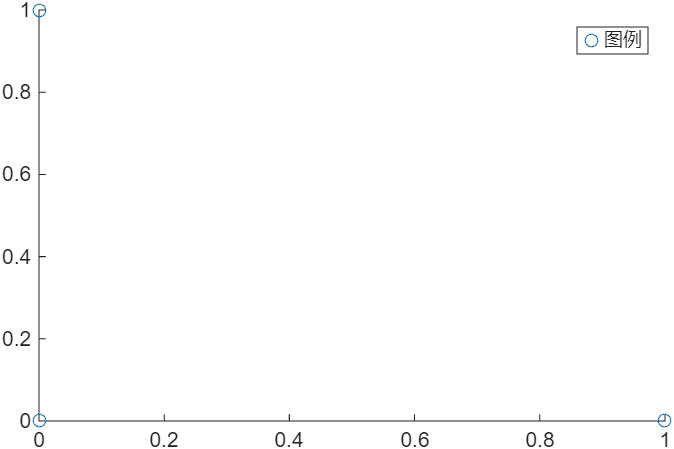

## 输入参数

GObjects，作图函数返回的图形对象。可以指定多个，但必须在同一坐标区内。

## 返回值

Location(1,1)string，优化的legend函数的Location参数。可能是["southwest","northwest","southeast","northeast"]之一。

**See also** [legend](matlab:doc legend)

function Location=OptimizedLegendLocation(GObjects)
persistent GroupLocation
if isempty(GroupLocation)
	GroupLocation=["southwest","northwest","southeast","northeast"];
end
Location=GObjects(1).Parent;
if isa(GObjects,'matlab.graphics.primitive.Polygon')
	GObjects=[GObjects.Shape];
	GObjects=vertcat(GObjects.Vertices);
	XData=GObjects(:,1);
	YData=GObjects(:,2);
else
	XData=vertcat(GObjects.XData);
	YData=vertcat(GObjects.YData);
end
[~,Location]=min(accumarray(((ruler2num(XData,Location.XAxis)>mean(ruler2num(xlim(Location),Location.XAxis)))*2+(ruler2num(YData,Location.YAxis)>mean(ruler2num(ylim(Location),Location.YAxis)))+1).',1,[4,1]));
Location=GroupLocation(Location);